Question5 

(b)  Write a function $\mathrm{simplesamplingSAW}\left(N\right)\;$ to use simple sampling to estimate the number of self-avoiding walks of length $1\ldotp \ldotp N$ . Test your function by comparing its output against the exact values for lengths up to 10, and give an estimate of the accuracy of your result.

The algorithm used in this implementation is taken from [2].

clear 
clc

%Actual values
N = [ 4  12 36 100 284 780 2172 5916 16268 44100 ];

%Store Value for max samples = 100000
tic
s(1) = simplesampling(1,100000);
%Repeat for other values of N
s(2) = simplesampling(2,100000);
s(3) = simplesampling(3,100000);
s(4) = simplesampling(4,100000);
s(5) = simplesampling(5,100000);
s(6) = simplesampling(6,100000);
s(7) = simplesampling(7,100000);
s(8) = simplesampling(8,100000);
s(9) = simplesampling(9,100000);
s(10) = simplesampling(10,100000);
toc

Elapsed time is 59.758439 seconds.


%Calculate error
for i = 1:10
    error(i) = abs(N(i)-s(i));
end
% Compare values
T = table(transpose(N),transpose(s),transpose(error));
T.Properties.VariableNames{1} = 'Actual Values';
T.Properties.VariableNames{2} = 'Simple Sampling Estimate';
T.Properties.VariableNames{3} = 'Simple Sampling Error';
T

T = 10×3 table
    Actual Values    Simple Sampling Estimate    Simple Sampling Error
    _____________    ________________________    _____________________

            4                        4                             0  
           12                 11.98912            0.0108800000000002  
           36                 36.04736            0.0473599999999976  
          100                 99.61728             0.382720000000006  
          284                284.48768             0.487680000000012  
          780                785.28512              5.28512000000001  
         2172               2171.53536             0.464640000000145  
         5916                5953.9456                       37.9456  
        16268               16082.5344                      185.4656  
        44100              45529.16992                    1429.16992  


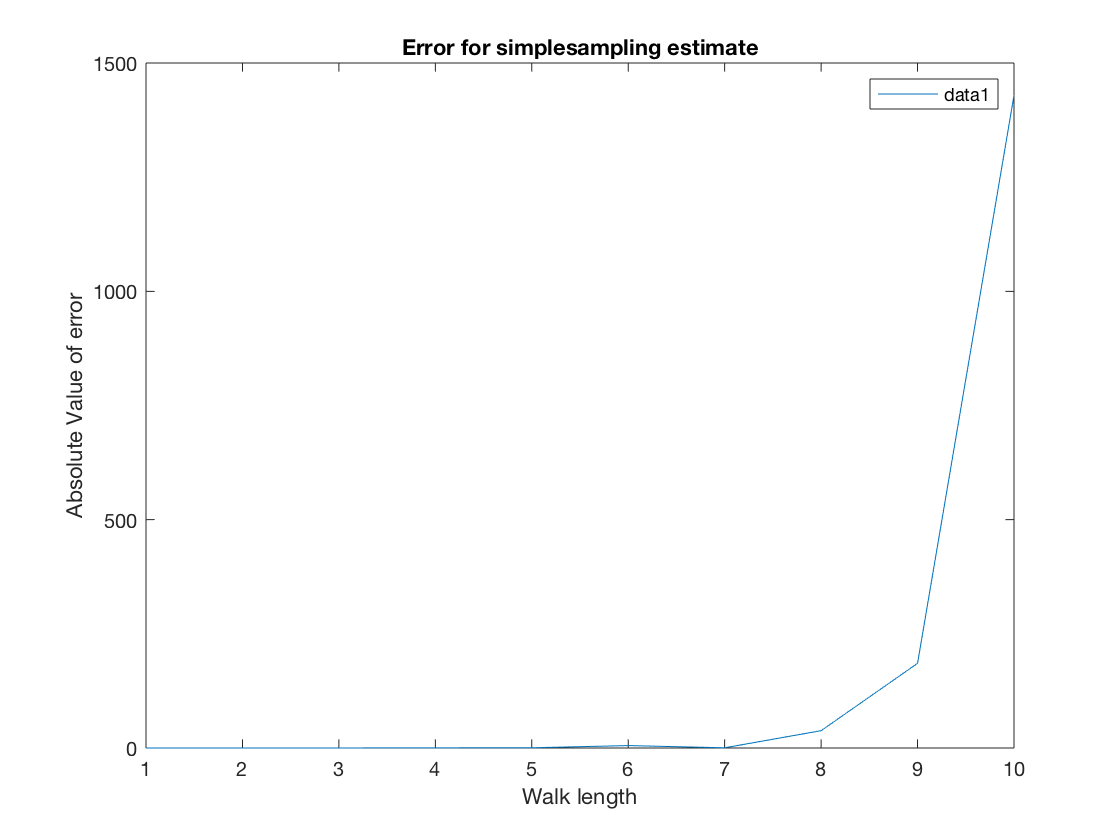

plot(error)
title('Error for simplesampling estimate')
xlabel('Walk length')
ylabel('Absolute Value of error')
legend()

For a managable number of trials (i.e N <= 10^7, which is a value I have tested,), we can't give an estimate for the number of self-avoiding random walks of length 50 with simple sampling because the directions are chosen randomly at every step which decreases the number of successful trials. Given max samples = N, the number of successful trials decreases as length of the walk increases. Hence, this method is not suitable for computing estimates for long walks. If we execute $simplesampling\left(50,10000000\right)$we will get 0 as our result 

function estimate = simplesampling(l,maxsamples)
    
    % l is length of the walk 
    % maxsamples is the number of trials that we want to run

    % Count of accepted trials (the ones that reach length l)
    s = 0;
    % Count of total number of trials performed
    samples = 0;
    
    while samples < maxsamples
        
        % Initiate lattice where we perform our walks before every trial to
        % 0. Every time we step to a new coordinate we mark 1. 
        lattice = zeros(2*l + 1 ,2*l + 1);
        % Increase trial count by 1 
        samples = samples + 1; 
        % Initiate steps performed in walk to 0 before every walk
        n = 0;
        % Start at origin
        x = l+1;
        y = l+1;
        % Mark origin
        lattice(x,y) = 1;
        
        % This is the while loop we use to walk around in the lattice. If
        % we reach the required walk length we break out of the loop
        while n < l
            
            % Pick random direction and move there
            z = randi(4,1);
            
            if z == 1
                x = x+1;
            elseif z == 2
                x = x-1;
            elseif z == 3
                y = y+1;
            elseif z == 4 
                y = y-1;
            end
            
            % If the walk self intersects (i.e we step to a position we have
            % visited before), we dispose the trial and start a new one by
            % skipping to the end of this while loop.  
            if lattice(x,y) == 1
                
                break
               
            % If we don't self intersect, we update the coordinate's value
            % to 1 and increase the number of steps taken
            else 
                
                lattice(x,y) = 1;
                n = n+1;
            
            end
           
        end
        % When we n = l, it means we had successful. Hence we increase our
        % count of s by 1
        if n == l
            s = s+1;
        end
    end
    %This is estimate of the total number of walks
    estimate = power(4,l)*s/maxsamples;
end